# Noise inspection: Colored noise

***This Script examines the influence of augmentation on white noise***

clc; close all; clear;
addpath(genpath(fullfile('../')));

## Pink noise examination

*We start from the assumption that the white noise signal is broadband and normally distributed.*

fs = 44100;                                % Sampling frequency of audio input
pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
noise = pink();
noise = noise/max(noise);
t = 0:1/fs:(length(noise)-1)/fs;

*The noise sample will be augmented using the Impulse response with duration = 1000ms coming from the front direction*

% IR Set with Duration = 1000ms
nameIR1000ms = 'IR44K_2s_1000ms';
dir = "aux_data/IR_Z_fixed/2s/";
IR1000ms = load(dir+nameIR1000ms).IR44K_2s_1000ms;
IR1000ms =IR1000ms(:,2);
IR1000ms = [IR1000ms{:}];

% Augmentation
noise_aug = conv(noise,IR1000ms(:,1));       
noise_aug = noise_aug(1:fs);
noise_aug = noise_aug/max(noise_aug);

*Inspect the ****Power spectrum**** of the noise samples using the**** Welch Method***

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       PSD Welch Method parameters     %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
segmentLength = 512;                    % Segments will be 512 samples (goes to 257 when taking positive frequencies only)
frame_overlap = segmentLength/2;        % 50 percent overlap
win = hamming(segmentLength);           % 512 sample-length hanning window
df = fs/(2*((segmentLength/2)+1));      %
f = 0:df:(fs-df)/2;                     %
N_bins = (segmentLength/2)+1;           %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% PSD estimation noise sample:
framed_fft = welch_window(noise, segmentLength, frame_overlap, win);
noise_psd = normalize(welch_input_fft(framed_fft, win, fs),'range');

% PSD estimation augmented noise sample:
framed_fft = welch_window(noise_aug, segmentLength, frame_overlap, win);
noise_aug_psd = normalize(welch_input_fft(framed_fft, win, fs),'range');

*Plot the time and frequency domain *

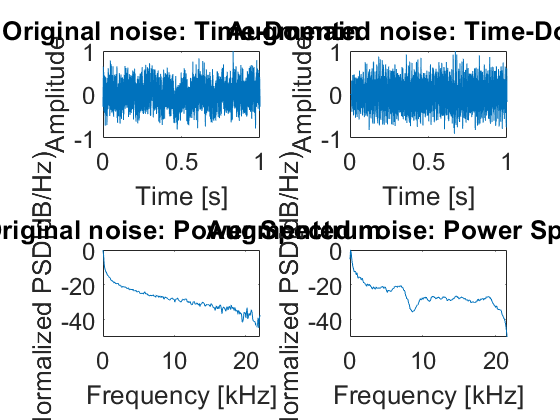

fig = figure;
fontsize = 18;
subplot(2,2,1); plot(t,noise); xlabel("Time [s]"); ylabel("Amplitude"); title("Original noise: Time-Domain", "FontSize", 36); 
ax = gca;
ax.FontSize = fontsize;
subplot(2,2,2); plot(t,noise_aug); xlabel("Time [s]"); ylabel("Amplitude"); title("Augmented noise: Time-Domain", "FontSize",36);
ax = gca;
ax.FontSize = fontsize;
subplot(2,2,3); plot(f/1000,10*log10(noise_psd)); xlabel("Frequency [kHz]"); ylabel("Normalized PSD[dB/Hz)"); title("Original noise: Power Spectrum","FontSize",36); ylim([-50 0]);
ax = gca;
ax.FontSize = fontsize;
subplot(2,2,4); plot(f/1000,10*log10(noise_aug_psd)); xlabel("Frequency [kHz]"); ylabel("Normalized PSD[dB/Hz)"); title("Augmented noise: Power Spectrum","FontSize",36); ylim([-50 0]);
ax = gca;
ax.FontSize = fontsize;

***Note: White noise passing through a channel can be considered colored noise, therefore white noise arriving in the microphone of our smartphone can also be considered colored noise.***

***If the original noise is already colored, showing lower power levels at high frequencies, the augmentation will generally be less effective. ***

***We can speculate that models will have a harder time detecting these types of noise***